clc;clear;close all;

## 1、生成点

warning off

x = [-0.093826014	-0.806885969	-0.869107424	-0.607593699	-0.198575088	0.071471147	0.029661741	-0.934851496	-0.99545664	-0.727493607	-0.324158268	-0.053914004	-0.094412496	-1.063279363	-1.120643666	-0.843342719	-0.447146847	-0.178018734	-0.219581389	-1.196420487	-1.244287821	-0.957747504	-0.566889496	-0.301995944	-0.345189896	-1.330480673	-1.365150227	-1.072432045	-0.684958264	-0.426634201	-0.471491248];
y = [0.77578231	0.356339095	0.321422276	0.513967924	0.806869414	0.987421948	0.955920465	0.529873656	0.496672287	0.683238574	0.974201572	1.156404048	1.130623057	0.704345321	0.670918585	0.847204765	1.138079186	1.320881008	1.307478193	0.882762041	0.843738154	1.008453692	1.296936146	1.489986794	1.482925709	1.062868127	1.013983851	1.169159842	1.454390881	1.662575673	1.659444452];
z = [-0.649490557	-0.460220532	0.022370579	0.40270091	0.408910321	0.039920367	-0.440404854	-0.457241977	0.027033473	0.402165041	0.409346636	0.044401455	-0.437564667	-0.454032072	0.031649719	0.401144624	0.40980008	0.048715634	-0.434954176	-0.452309049	0.036228055	0.400934593	0.409679859	0.053221736	-0.431428721	-0.450248226	0.040734097	0.401829121	0.410177898	0.057843748	-0.427963737];

Points = [x;y;z];

P1 = [-0.993222065  1.543033979 -0.739390832];
P2 = [-0.3018782 0.469032011 -0.740672156];


PAB = [-0.751, 1.002, -0.735];

PointsIn = [-0.66805761 -0.273486396 -0.27698154;-0.741470579	0.221444522 -0.499925631;1.037917729 1.298784925 1.315527469];


## 2、拟合


[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Points,P1,P2);



## 3、AB面

numShengLu = 5;
phi = pi/2/90*65;

toff = zeros(1,2*numShengLu);
roff = zeros(1,2*numShengLu);


toff(1) = 0.0558;
roff(1) = -0.1137;

Ang = -ShengLuJiaoJiSuan(numShengLu);


[PointA,PointB,BianHao] = Calculat_A_and_B_Points_after_Offest2(Bottom_round_center1',Bottom_round_center2',MTaon',Mcenter',Mradial,PAB',phi,Ang,toff,roff)

PointA =    -0.4736   -0.1188   -0.0316   -0.1188   -0.3572   -1.0084   -1.2468   -1.3340   -1.2468   -0.8920
    1.0978    1.1579    1.1744    1.1579    1.1128    0.9894    0.9442    0.9277    0.9442    1.0044
   -0.7094   -0.4423   -0.1419    0.1584    0.3783    0.3783    0.1584   -0.1419   -0.4423   -0.7094


PointB =    -0.7936   -0.9634   -1.0069   -0.9634   -0.8448   -0.5208   -0.4021   -0.3587   -0.4021   -0.5720
    0.8676    0.5504    0.4729    0.5504    0.7620    1.3401    1.5518    1.6292    1.5518    1.2346
   -0.7094   -0.4423   -0.1419    0.1584    0.3783    0.3783    0.1584   -0.1419   -0.4423   -0.7094


BianHao =      1     3     5     7     9    10     8     6     4     2
     1     3     5     7     9    10     8     6     4     2


## 4、画图

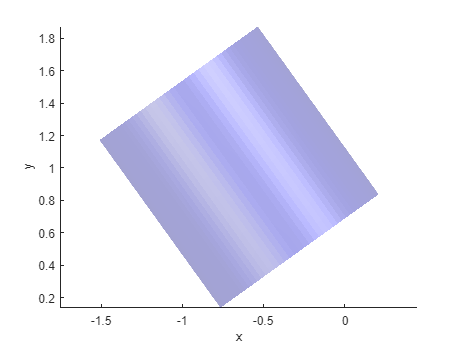

figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;

lighting flat;


## 5、点画图

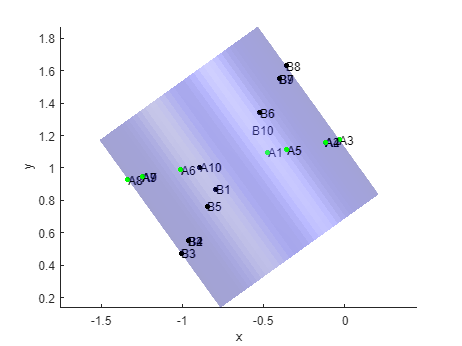

scatter3(PointA(1,1),PointA(2,1),PointA(3,1),20,'filled','green')
text(PointA(1,1),PointA(2,1),PointA(3,1),'A1')
scatter3(PointA(1,2),PointA(2,2),PointA(3,2),20,'filled','green')
text(PointA(1,2),PointA(2,2),PointA(3,2),'A2')
scatter3(PointA(1,3),PointA(2,3),PointA(3,3),20,'filled','green')
text(PointA(1,3),PointA(2,3),PointA(3,3),'A3')
scatter3(PointA(1,4),PointA(2,4),PointA(3,4),20,'filled','green')
text(PointA(1,4),PointA(2,4),PointA(3,4),'A4')
scatter3(PointA(1,5),PointA(2,5),PointA(3,5),20,'filled','green')
text(PointA(1,5),PointA(2,5),PointA(3,5),'A5')
scatter3(PointA(1,6),PointA(2,6),PointA(3,6),20,'filled','green')
text(PointA(1,6),PointA(2,6),PointA(3,6),'A6')
scatter3(PointA(1,7),PointA(2,7),PointA(3,7),20,'filled','green')
text(PointA(1,7),PointA(2,7),PointA(3,7),'A7')
scatter3(PointA(1,8),PointA(2,8),PointA(3,8),20,'filled','green')
text(PointA(1,8),PointA(2,8),PointA(3,8),'A8')
scatter3(PointA(1,9),PointA(2,9),PointA(3,9),20,'filled','green')
text(PointA(1,9),PointA(2,9),PointA(3,9),'A9')
scatter3(PointA(1,10),PointA(2,10),PointA(3,10),20,'filled','green')
text(PointA(1,10),PointA(2,10),PointA(3,10),'A10')

scatter3(PointB(1,1),PointB(2,1),PointB(3,1),20,'filled','black')
text(PointB(1,1),PointB(2,1),PointB(3,1),'B1')
scatter3(PointB(1,2),PointB(2,2),PointB(3,2),20,'filled','black')
text(PointB(1,2),PointB(2,2),PointB(3,2),'B2')
scatter3(PointB(1,3),PointB(2,3),PointB(3,3),20,'filled','black')
text(PointB(1,3),PointB(2,3),PointB(3,3),'B3')
scatter3(PointB(1,4),PointB(2,4),PointB(3,4),20,'filled','black')
text(PointB(1,4),PointB(2,4),PointB(3,4),'B4')
scatter3(PointB(1,5),PointB(2,5),PointB(3,5),20,'filled','black')
text(PointB(1,5),PointB(2,5),PointB(3,5),'B5')
scatter3(PointB(1,6),PointB(2,6),PointB(3,6),20,'filled','black')
text(PointB(1,6),PointB(2,6),PointB(3,6),'B6')
scatter3(PointB(1,7),PointB(2,7),PointB(3,7),20,'filled','black')
text(PointB(1,7),PointB(2,7),PointB(3,7),'B7')
scatter3(PointB(1,8),PointB(2,8),PointB(3,8),20,'filled','black')
text(PointB(1,8),PointB(2,8),PointB(3,8),'B8')
scatter3(PointB(1,9),PointB(2,9),PointB(3,9),20,'filled','black')
text(PointB(1,9),PointB(2,9),PointB(3,9),'B9')
scatter3(PointA(1,10),PointA(2,10),PointA(3,10),20,'filled','black')
text(PointB(1,10),PointB(2,10),PointB(3,10),'B10')


Mradial

Mradial = 0.6007

testDis =  norm(PointA(:,8)-PointB(:,3))

testDis = 0.5602

## 6、测试

%偏移后A1
a = PointB(:,1)';
[xxN1,yyN1,zzN1] = foot_of_perpendicular_from_a_point_to_a_line(a,Bottom_round_center1,Bottom_round_center2);
aa = [xxN1,yyN1,zzN1];

%偏移前A1
b = [-0.844827296956774	0.761980967215612	-0.662136964726789];

[xxN2,yyN2,zzN2] = foot_of_perpendicular_from_a_point_to_a_line(b,Bottom_round_center1,Bottom_round_center2);
bb = [xxN2,yyN2,zzN2];

norm(aa-bb)

ans = 0.0558